# Lab Template

This is an mlx (matlab live script) template for the labs. Live Script allows you to mix code with text. Try to structure you code with one cell/section per exercise and keep all functions in the ./functions directory and all images in the ./images directory.

## Setting up environment

Here we clear old variables and make sure that ./functions and ./images are in the path.

% use clear to avoid unknowingly being dependent on 
% variables in the workspace defined by other scripts
% or in the command window
clear;

%add ./functions and ./images folders to path
addpath('./functions');
addpath('./images');

#### Command shortlist:

- "%% Exercise 3": Create a new section called "Exercise 3"

- ctrl+shift+enter: Run section

- ctrl+e:  Switch between text and code mode for selected lines

- ctrl+E: Write equation (syntax similar to latex math)

## Exercise 3.2

Yes it does

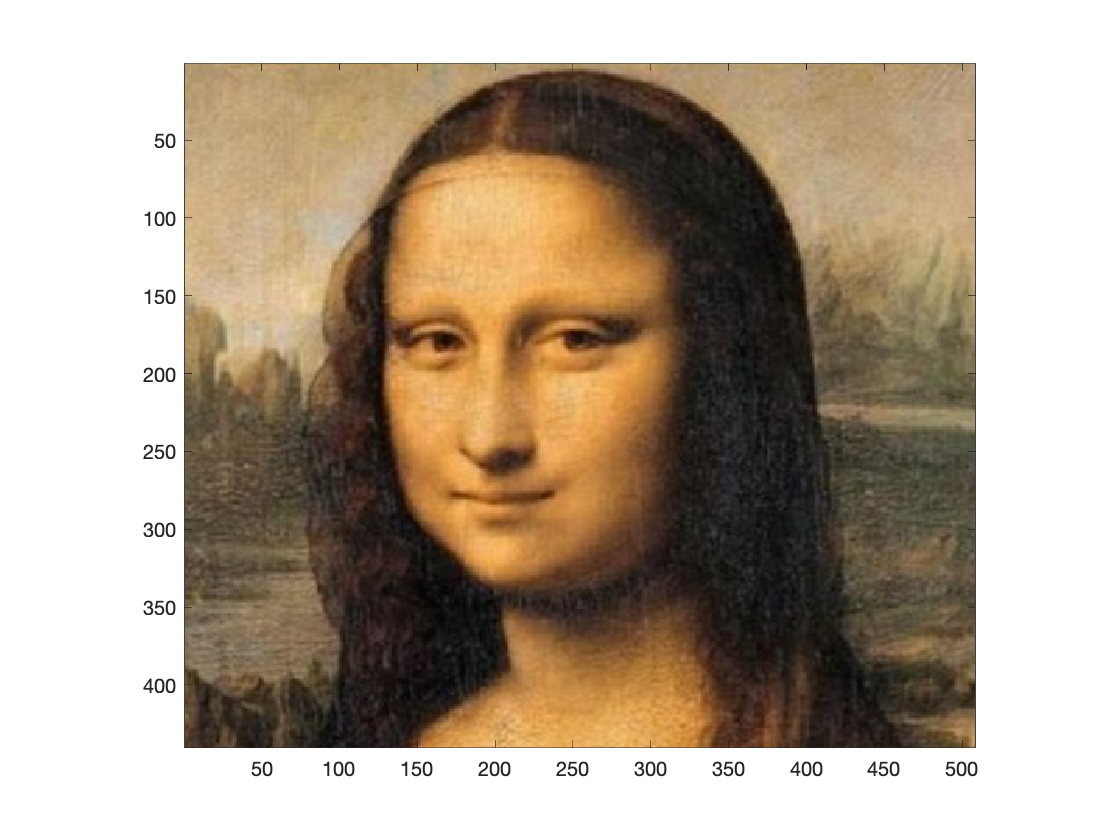

img  = read_image('examples/mona.png');
imagesc(img);
axis image

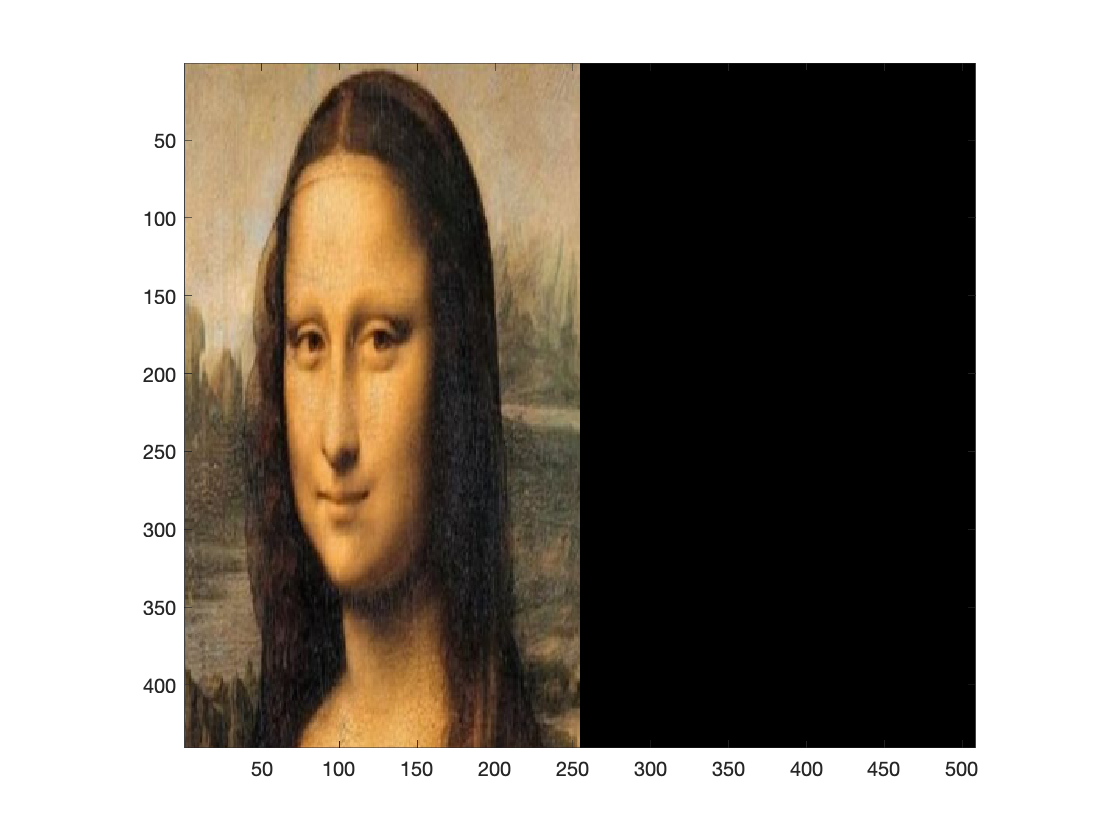

A = [0.88 -0.48; 0.48 0.88];
A = [2 0; 0 1];
%A = eye(2);
t = [100;-100];
t = [0;0];
target_size = size(img);
wraped = affine_warp(target_size,img,A,t);
imagesc(wraped);
axis image

## Exercise 3.3

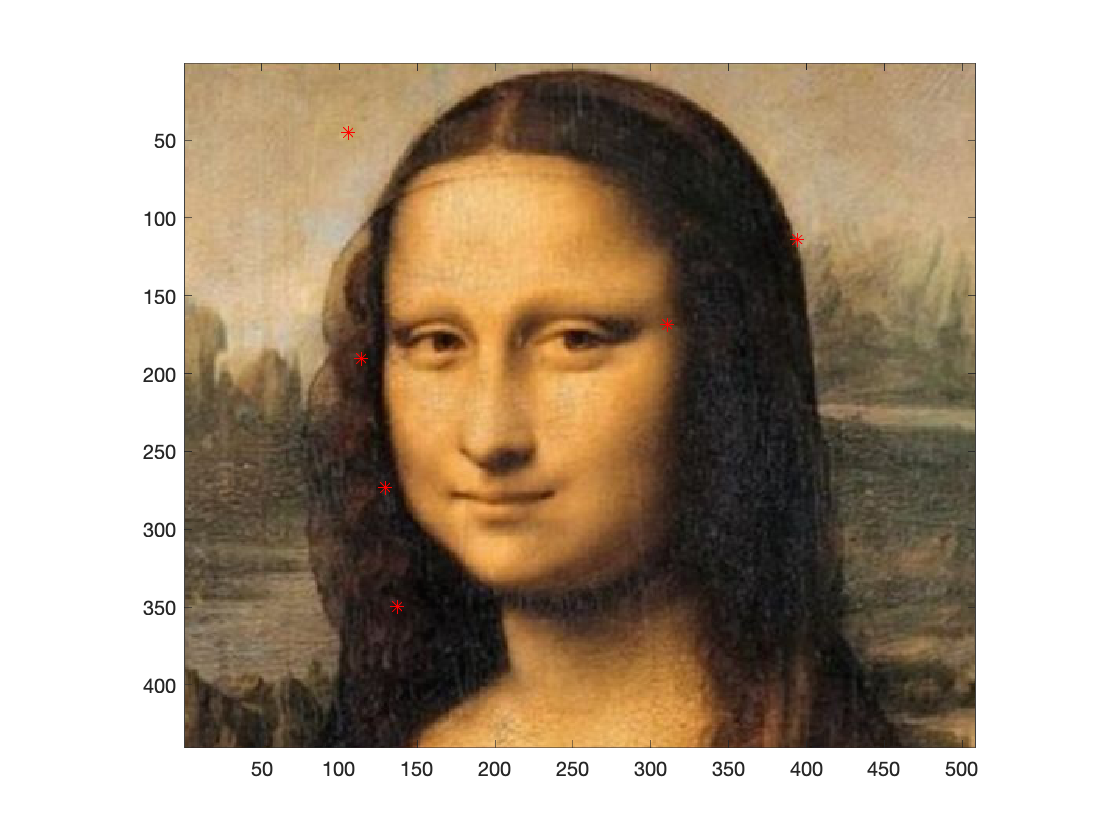

clf;
%[pts,pts_tilde,A_true,t_true] = affine_test_case
A = [1 0; 0 1];
t = [0;0];
pts = 440*rand(2,6);
pts_tilde = affine_warp(size(pts),pts,A,t);%A*pts(1:2,:)+t;
imagesc(img), hold on;
scatter(pts(1,:),pts(2,:),'*','r')
axis image
hold off;

target_size_pts = size(pts);
target_size_img = size(img);
img_tilde = affine_warp(target_size_img,img,A,t);
imagesc(img_tilde), hold on;
scatter(pts_tilde(1,1:end),pts_tilde(2,1:end),'*','r')
axis image
hold off;

## Exercise 3.4

outlier_rate = 0.1;
[pts,pts_tilde,A_true,t_true] = affine_test_case(outlier_rate);
[A, t] = estimate_affine(pts, pts_tilde);

threshold = 1e-14;

if(A-A_true < threshold)
    fprintf("A is perfect")
else
    fprintf("Clearly A does not work")
end

A is perfect

if(t-t_true < threshold)
    fprintf("t is perfect")
else
    fprintf("Clearly t does not work")
end

t is perfect

## Exercise 3.5

Residual_lgths.m

## Exercise 3.6

## Exercise 3.7

threshold = 0.01;
[pts,pts_tilde,A_true,t_true] = affine_test_case(outlier_rate);
[A,t] = ransac_fit_affine(pts, pts_tilde, threshold);

## Exercise 3.8

%[pts1, descs1] = extractSIFT(mean(img1,3));
%[pts2, descs2] = extractSIFT(mean(img2,3));
%corrs = matchFeatures(descs1', descs2', 'MaxRatio', 0.8, 'MatchThreshold', 100);

## Exercise 3.9

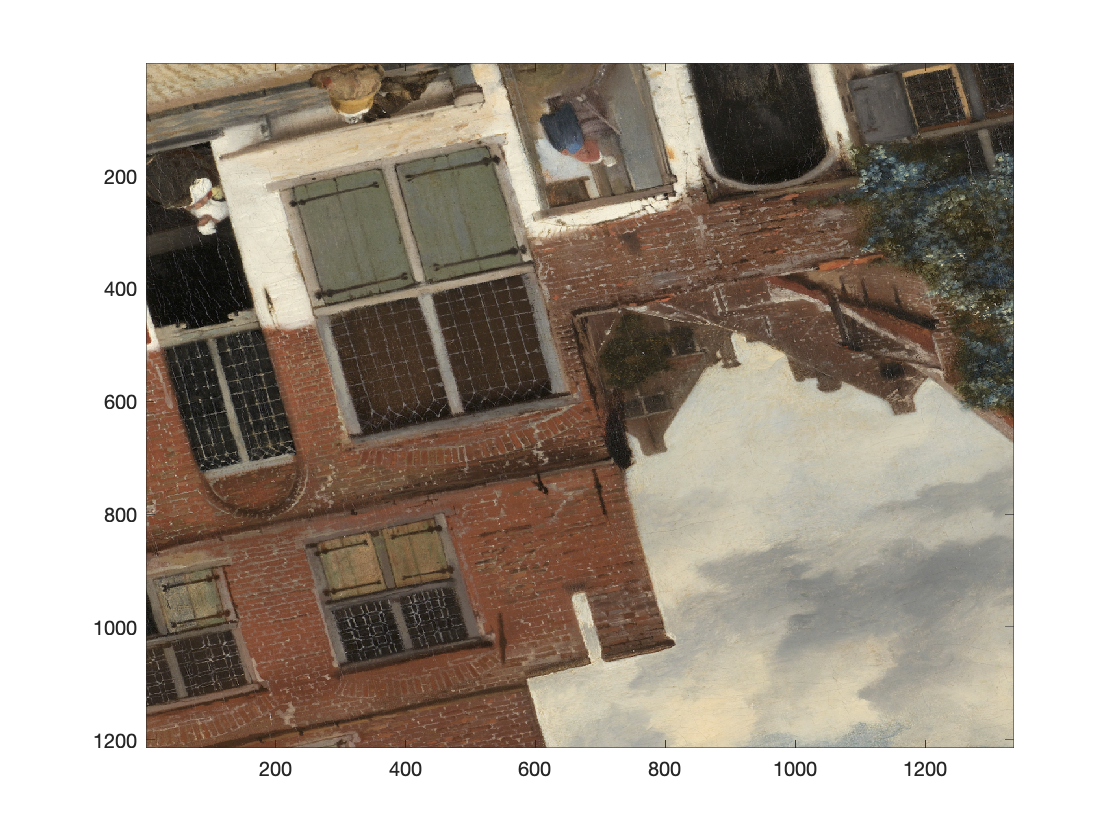

ver_source = read_image('vermeer_source.png');
ver_target = read_image('vermeer_target.png');
imagesc(ver_source);

warped = align_images(ver_source, ver_target, 0.01,false);

Invalid MEX-file '/Users/haithambabbili/Document/University/First Year/Second Semester/Imag Analyses/Projects/collaction/SSY098-Image_Analysis-master/Project 2/lab_template/sift/vl_sift.mexmaci64': dlopen(/Users/haithambabbili/Document/University/First Year/Second Semester/Imag Analyses/Projects/collaction/SSY098-Image_Analysis-master/Project 2/lab_template/sift/vl_sift.mexmaci64, 6): no suitable image found.  Did find:
	/Users/haithambabbili/Document/University/First Year/Second Semester/Imag Analyses/Projects/collaction/SSY098-Image_Analysis-master/Project 2/lab_template/sift/vl_sift.mexmaci64: code signature in (/Users/haithambabbili/Document/University/First Year/Second Semester/Imag Analyses/Projects/collaction/SSY098-Image_Analysis-master/Project 2/lab_template/sift/vl_sift.mexmaci64) not valid for use in process using Library Validation: library load disallowed by system policy

Error in 

imagesc(ver_target);
imagesc(warped);
imwrite(warped, 'vermeer_warped.png')
% 
% switch_plot(wraped,ver_target)


## Exercise 3.10

CT_1 = read_image('CT_1.jpg');
CT_2 = read_image('CT_2.jpg');
imwrite(CT_2, 'CT_target.jpg')
warped = align_images(CT_1,CT_2,10,true);

imagesc(CT_1), colormap gray, axis image
imagesc(CT_2), colormap gray, axis image
imagesc(warped), colormap gray, axis image
imwrite(warped, 'CT_warped.jpg')

## Exercise 3.11

tissue_f = read_as_grayscale('tissue_fluorescent.tif');
tissue_b = read_as_grayscale('tissue_brightfield.tif');
inverted_tissue_b = 1 - tissue_b;
imwrite(inverted_tissue_b, 'tissue_target.tif')
warped = align_images(tissue_f,inverted_tissue_b,10,true);

imagesc(tissue_f), axis image
imagesc(inverted_tissue_b), axis image
imagesc(warped), axis image
imwrite(warped, 'tissue_warped.tif')

## Exercise 3.13

s_img = read_image('source_16x16.tif');
warped = warp_16x16(s_img);
imagesc(s_img), colormap gray
imagesc(warped),colormap gray

## Exercise 3.14

tissue_f = read_as_grayscale('tissue_fluorescent.tif');
tissue_b = read_as_grayscale('tissue_brightfield.tif');
inverted_tissue_b = 1 - tissue_b;

warped = align_images(tissue_f,inverted_tissue_b,10,true);

imagesc(tissue_f), axis image
imagesc(inverted_tissue_b), axis image
imagesc(warped), axis image